# Exercise 1

Create and test a function that given euler axis/angle information returns the rotation matrix. Do the next verifications: 

- Calculate the determinant 

- Ensure that the transpose operation is equivalent to the inverse

 - Observe what happens to a vector parallel to the axis direction 

- Observe what happens to a vector perpendicular to the axis direction

disp('EX1')

EX1


disp(' ')

u = [1 2 1]';
R = euleruphi2matrix(u, 45)

Your angle was changed from degrees to radians in order to operate


R =     0.7559   -0.1910    0.6262
    0.3863    0.9024   -0.1910
   -0.5285    0.3863    0.7559


determinant = det(R)

determinant = 1.0000

inverse = inv(R)

inverse =     0.7559    0.3863   -0.5285
   -0.1910    0.9024    0.3863
    0.6262   -0.1910    0.7559


transposed = transpose(R)

transposed =     0.7559    0.3863   -0.5285
   -0.1910    0.9024    0.3863
    0.6262   -0.1910    0.7559


disp('parallel vector: ')

parallel vector: 


v = 5*u

v =      5
    10
     5


disp('when rotated: ')

when rotated: 


w = R*v

w =     5.0000
   10.0000
    5.0000


disp('perpendicular vector: ')

perpendicular vector: 


y=1;z=1;x=(-u(2)*y-u(3)*z)/u(1);
v= [x y z]'

v =     -3
     1
     1


disp('when rotated: ')

when rotated: 


w = R*v

w =    -1.8326
   -0.4476
    2.7278


## Exercise 2

Use the past function and the function Cubeplot/Cubeplot2 to transform the orientation of the cube given by M Find the rotation vectors that makes: 

- The green face points in the positive z direction and the orange face in the -y direction 

- The orange face points in the -z direction and the blue face into the +y direction 

- The red face points on the -x direction and the blue face into the -y direction.

disp('EX2')

EX2


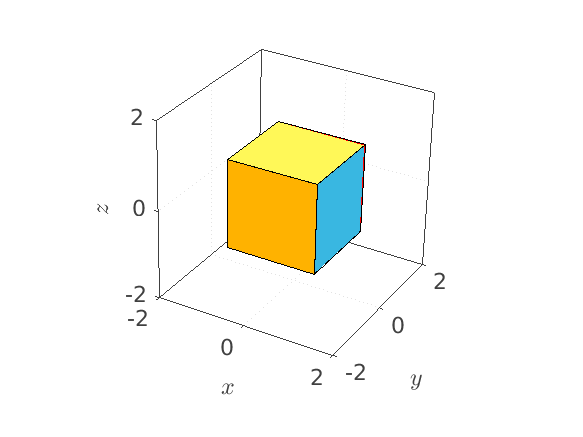

M = [    -1  -1 1;   %Node 1
    -1   1 1;   %Node 2
    1   1 1;   %Node 3
    1  -1 1;   %Node 4
    -1  -1 -1;  %Node 5
    -1   1 -1;  %Node 6
    1   1 -1;  %Node 7
    1  -1 -1]; %Node 8

Cubeplot(M);


R = euleruphi2matrix([0 1 0]', 90);

Your angle was changed from degrees to radians in order to operate


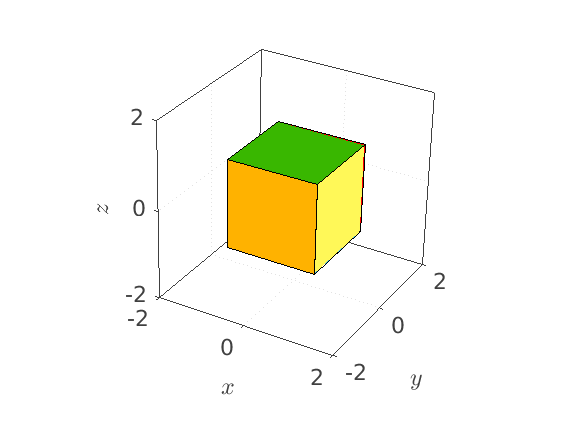

N = R*M';
% Call to Cubeplot
Cubeplot(N');


R = euleruphi2matrix([1 1 1]', 120);

Your angle was changed from degrees to radians in order to operate


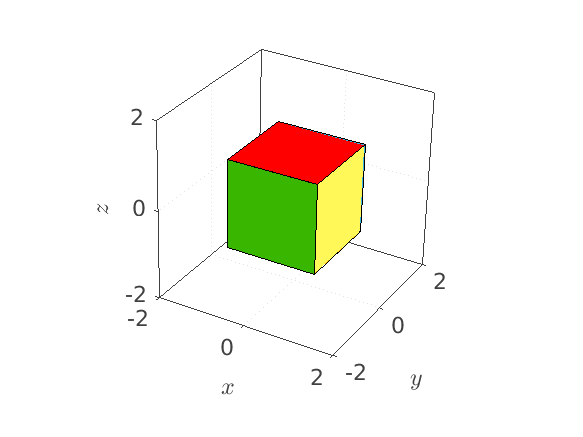

N = R*M';
% Call to Cubeplot
Cubeplot(N');


R = euleruphi2matrix([1 -1 0]', 180);

Your angle was changed from degrees to radians in order to operate


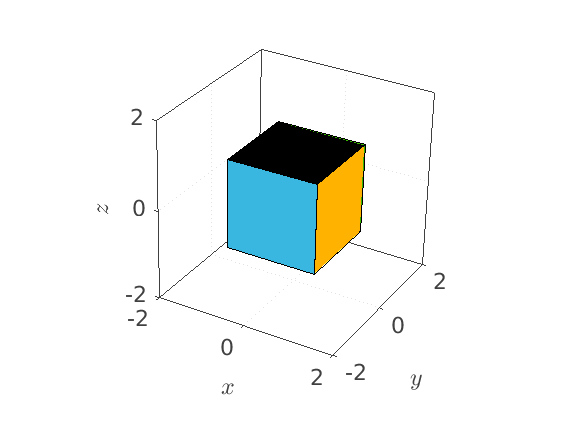

N = R*M';
% Call to Cubeplot
Cubeplot(N');

## Exercise 3

Create a function that implements the quaternion multiplication. Create a function that given a vector and a quaternion, return the vector rotated by the attitude encoded in the quaternion using quaternion multiplications. Test it an argument/demonstrate why your function is well implemented.

disp('EX3')

EX3


v = [1 0 0];
q = [sqrt(2)/2 0 0 sqrt(2)/2];
w = rotquat (v, q)

Your vector was reshaped to a (3, 1) vector in order to operate
Your quaternion was reshaped to a (4, 1) vector in order to operate


w =     0.0000
    1.0000
         0


## Exercise 4

Create a large set of rotation matrices (at least 100) for which the euler axis may be random (not necessarily random, but not the same) and the euler angle in increasing order form 0 to 6 pi. (Use a FOR LOOP) Make a plot of the trace of this matrices with the value of the angle in the x axis i.e. Trace(R(phi,e)) vs. \phi . Explain what you observe.

disp('EX4')

EX4


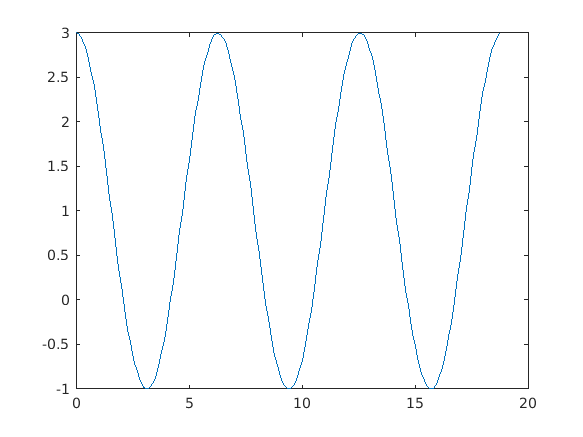

ang = [];
tr = [];
for  phi = 0:0.1:6*pi
    ang = [ang; phi];
    v = rand(3, 1);
    R = euleruphi2matrix(v, phi);
    tr = [tr; trace(R)];
end
figure;
plot(ang, tr);

fprintf('We can see that no matter the axis, the trace follows a sinusoidal path as the angle is\naugmented, then we can assume that it only depends on the angle.')

We can see that no matter the axis, the trace follows a sinusoidal path as the angle is
augmented, then we can assume that it only depends on the angle.

## Exercise 5

Create a function that given a set of euler angles, return its respective rotation matrix. Create also a function that given a rotation matrix return the respective rotation angles. -Ensure that the case for which theta = pi/2 + k*pi with k=1,2,.. is well implemented

disp('EX5')

EX5


R = eulerangles2matrix(90, 0, 45)

Your roll angle was changed from degrees to radians in order to operate
Your yaw angle was changed from degrees to radians in order to operate


R =     0.7071   -0.0000    0.7071
    0.7071    0.0000   -0.7071
         0    1.0000    0.0000


[roll, pitch, yaw] = matrix2eulerangles(R)

roll = 90

pitch = 0

yaw = 45


R = eulerangles2matrix(0, 90, 0)

Your pitch angle was changed from degrees to radians in order to operate


R =     0.0000         0    1.0000
         0    1.0000         0
   -1.0000         0    0.0000


[roll, pitch, yaw] = matrix2eulerangles(R)

pitch is equal to pi/2, cannot calculate roll and yaw


roll = "NaN"

pitch = 90

yaw = "NaN"